clear all
close all

lambda = 1000;

x_point_1 = 0/lambda;
z_point_1 = 0/lambda;

x_point_2 = 9.3048e+03/lambda;
z_point_2 = 1.9954e+04/lambda;

x_point_3 = 1.4236e+04/lambda;
z_point_3 = 1.9954e+04/lambda;

x_point_4 = 1.4236e+04/lambda;
z_point_4 = 15534/lambda;

x_point_5 = 6992/lambda;
z_point_5 = 0/lambda;


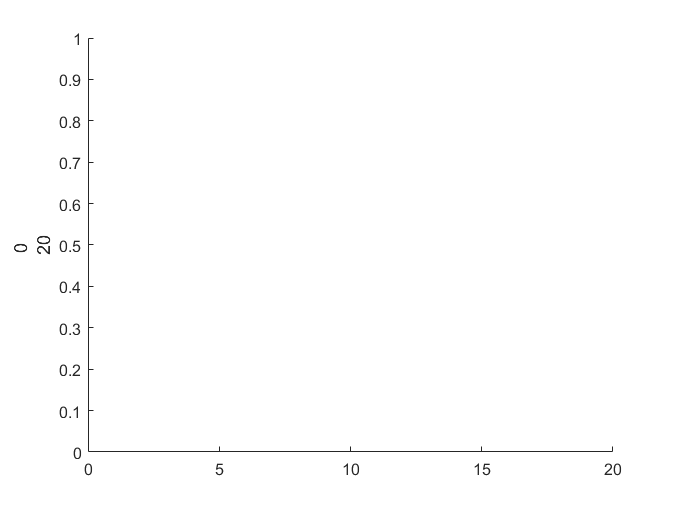

% for i = 1 : 0.1 : 100
%     z(i) = z_point_2 - R;
%     z = tand(65)*x + R;
% end


R = 3;
z1 = @(x) z_point_2 - R;
z2 = @(x) tand(65)*x - 2*tand(65);
x = fzero(@(x)z1(x)-z2(x), 0);
z = z2(x);

X_point = horzcat(x_point_1, x_point_2, x_point_3, x_point_4, x_point_5);
Z_point = horzcat(z_point_1, z_point_2, z_point_3, z_point_4, z_point_5);

hold on
angle = 0:0.1:2*pi;
% plot(X_point, Z_point, x, z, 'o', 1:20, z2(1:20),'black', 1:5, z1(1:5), 'xblack')
% plot(x + R*sin(angle), z + R*cos(angle), 'r')
xlim([0,20])
ylabel([0,20])

xo1_int1 = 9170/lambda;         
zo1_int1 = 19665/lambda;

xo1_int2 = 9623/lambda;
zo1_int2 = 19954/lambda;

xo1_centr = 9623/lambda; 
zo1_centr = 19454/lambda;


% o1_int1 = [9170, 19665]/lambda;
% o1_int2 = [9623, 19954]/lambda;
% o1_centr = [9623, 19454]/lambda;
pc = struct('int1', {[]}, 'int2', {[]}, 'centr', {[]}, 'r', {[]});

% begin
pc(1).int1 = [155, 0]/lambda;
pc(1).int2 = [294, 634]/lambda;
pc(1).centr = [1655, 0]/lambda;
pc(1).r = 1500/lambda;

pc(2).int1 = [9170, 19665]/lambda;
pc(2).int2 = [9623, 19954]/lambda;
pc(2).centr = [9623, 19454]/lambda;
pc(2).r = 500/lambda;

pc(3).int1 = [13718, 19954]/lambda;
pc(3).int2 = [14218, 19454]/lambda;
pc(3).centr = [13718, 19454]/lambda;
pc(3).r = 500/lambda;

pc(4).int1 = [14218, 15829]/lambda;
pc(4).int2 = [14077, 15195]/lambda;
pc(4).centr = [12718, 15829]/lambda;
pc(4).r = 1500/lambda;

pc(5).int1 = [7287, 634]/lambda;
pc(5).int2 = [7147, 0]/lambda;
pc(5).centr = [8647, 0]/lambda;
pc(5).r = 1500/lambda;


% r1 = 500/lambda;
% 
% hold on
% phi = 0:0.05:2*pi;
% plot(X_point, Z_point, x, z, 'o', 1:20, z2(1:20),'black', 1:5, z1(1:5), 'xblack')
% plot(xo1_centr + r1*cos(phi), zo1_centr + r1*sin(phi), 'r')
% xlim([0,40])
% ylabel([0,40])

% r1 = 
% l12 = sqrt((pc(1).int1(1) - pc(2).int1(1))^2 + (pc(1).int1(2) - pc(2).int1(2))^2); 
% l23 = sqrt((x_point_2 - x_point_3)^2 + (z_point_2 - z_point_3)^2);
% l34 = sqrt((x_point_4 - x_point_3)^2 + (z_point_4 - z_point_3)^2);
% l45 = sqrt((x_point_5 - x_point_4)^2 + (z_point_5 - z_point_4)^2);

% a = sqrt((pc(1).int1(1)-pc(1).centr(1))^2 + (pc(1).int1(2)-pc(1).centr(2))^2);
% b = sqrt((pc(1).int2(1)-pc(1).centr(1))^2 + (pc(1).int2(2)-pc(1).centr(2))^2);
% acos()
% 
% dot([pc(1).int1(1) - pc(1).centr(1), pc(1).int1(2) - pc(1).centr(2)],...
% [pc(1).int2(1) - pc(1).centr(1), pc(1).int2(2) - pc(1).centr(2)])

% первая окружность (1/4 окружности)
phi_1_begin = 0; % относительно оси х
phi_1_end = acosd( ...
                 (pc(1).centr(1)-pc(1).int2(1)) ...
                  /pc(1).r)

phi_1_end = 24.8606

dphi_1 = phi_1_end - phi_1_begin;

% вторая окружность 
phi_2_begin = acosd( ...
                 (pc(2).centr(1)-pc(2).int1(1)) ...
                  /pc(2).r); % относительно оси х
phi_2_end = acosd( ...
                 (pc(2).centr(1)-pc(2).int2(1)) ...
                  /pc(2).r);
dphi_2 = phi_2_end - phi_2_begin;

% третья окружность 
phi_3_begin = acosd( ...
                 (pc(3).centr(1)-pc(3).int1(1)) ...
                  /pc(3).r); % относительно оси х
phi_3_end = acosd( ...
                 (pc(3).centr(1)-pc(3).int2(1)) ...
                  /pc(3).r);
dphi_3 = phi_3_end - phi_3_begin;

% четверта окружность
phi_4_begin = acosd( ...
                 (pc(4).centr(1)-pc(4).int1(1)) ...
                  /pc(4).r); % относительно оси х
phi_4_end = acosd( ...
                 (pc(4).centr(1)-pc(4).int2(1)) ...
                  /pc(4).r);
dphi_4 = abs(phi_4_end - phi_4_begin);

% пятая окружность
phi_5_begin = acosd( ...
                 (pc(5).centr(1)-pc(5).int1(1)) ...
                  /pc(5).r);
phi_5_end = acosd( ...
                 (pc(5).centr(1)-pc(5).int2(1)) ...
                  /pc(5).r);
dphi_5 = abs(phi_5_end - phi_5_begin);

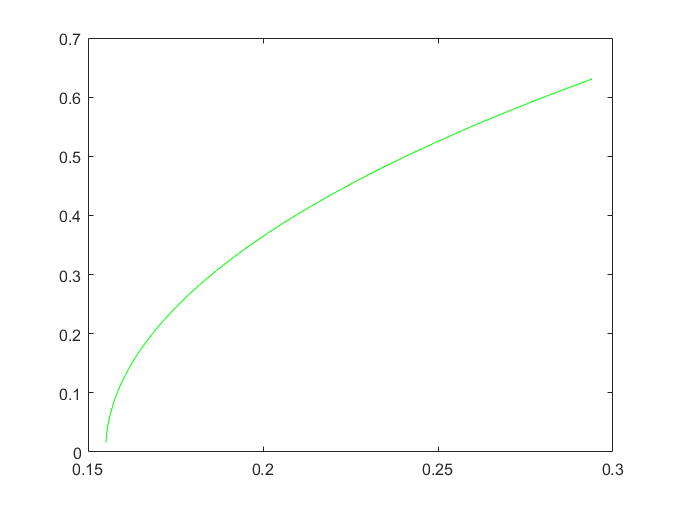

%%% Построим дугу окружности 1

N1_t = 40;
R1 = pc(1).r;
% угловой шаг окружности
for i = 1 : N1_t
    phid_step = dphi_1/N1_t;
    t1(i) = phid_step*i;
    dx1_c(i) = 2*R1*sind(dphi_1/2);
end

x1_c = pc(1).centr(1);
z1_c = pc(1).centr(2);

x1_r = R1*cosd(-t1+180) + x1_c;
z1_r = R1*sind(-t1+180) + z1_c;

figure;
plot(x1_r, z1_r,'g')

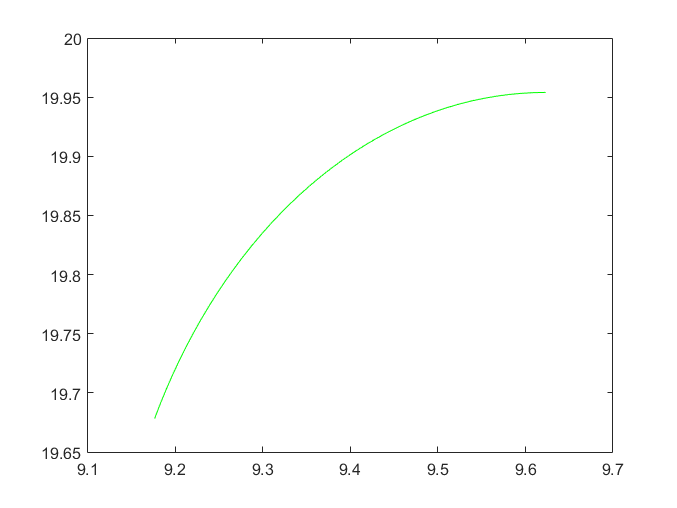

%%% Построим дугу окружности 2

N2_t = 40;
R2 = pc(2).r;
% угловой шаг окружности
for i = 1 : N2_t
    phid_step = dphi_2/N2_t;
    t2(i) = phi_2_begin + phid_step*i;
    dx2_c(i) = 2*R2*sind(dphi_2/2);
end

x2_c = pc(2).centr(1);
z2_c = pc(2).centr(2);

x2_r = R2*cosd(-t2+180) + x2_c;
z2_r = R2*sind(-t2+180) + z2_c;

figure;
plot(x2_r, z2_r,'g')

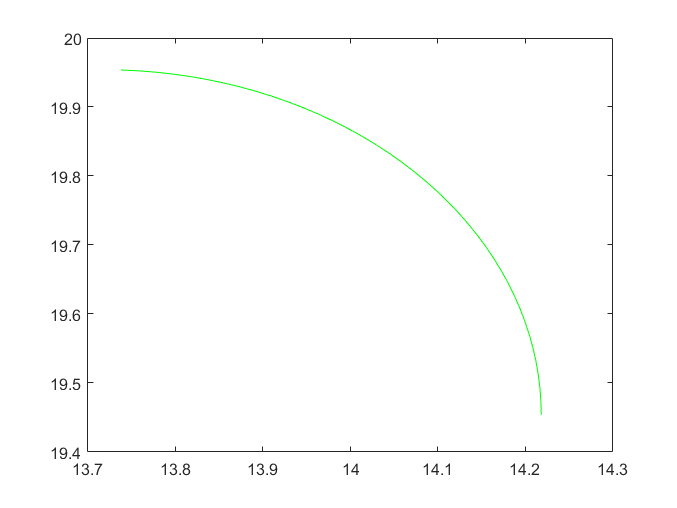

%%% Построим дугу окружности 3

N3_t = 40;
R3 = pc(3).r;
% угловой шаг окружности
for i = 1 : N3_t
    phid_step = dphi_3/N3_t;
    t3(i) = phi_3_begin + phid_step*i;
    dx3_c(i) = 2*R3*sind(dphi_3/2);
end

x3_c = pc(3).centr(1);
z3_c = pc(3).centr(2);

x3_r = R3*cosd(-t3+180) + x3_c;
z3_r = R3*sind(-t3+180) + z3_c;

figure;
plot(x3_r, z3_r,'g')

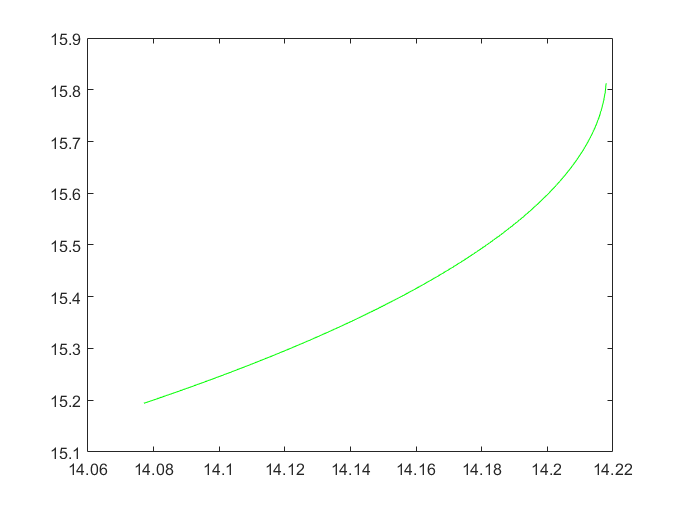

%%% Построим дугу окружности 4

N4_t = 40;
R4 = pc(4).r;
% угловой шаг окружности
for i = 1 : N4_t
    phid_step = dphi_4/N4_t;
    t4(i) =  phid_step*i;
    dx4_c(i) = 2*R4*sind(dphi_4/2);
end

x4_c = pc(4).centr(1);
z4_c = pc(4).centr(2);

x4_r = R4*cosd(-t4) + x4_c;
z4_r = R4*sind(-t4) + z4_c;

figure;
plot(x4_r, z4_r,'g')

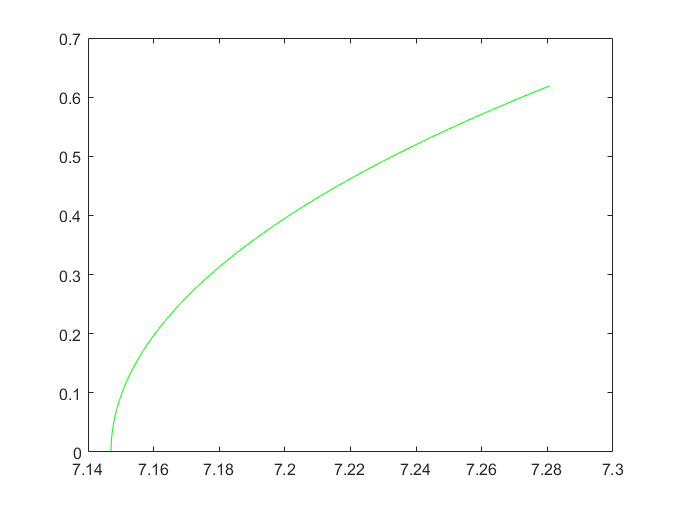

%%% Построим дугу окружности 4

N5_t = 40;
R5 = pc(5).r;
% угловой шаг окружности
for i = 1 : N5_t
    phid_step = dphi_5/N5_t;
    t5(i) = 90 + 65 + phid_step*i;
    dx5_c(i) = 2*R5*sind(dphi_5/2);
end

x5_c = pc(5).centr(1);
z5_c = pc(5).centr(2);

x5_r = R5*cosd(t5) + x5_c;
z5_r = R5*sind(t5) + z5_c;

figure;
plot(x5_r, z5_r,'g')

% Порядок точек
x1 = pc(1).int1(1);
x2 = pc(1).int2(1);
x3 = pc(2).int1(1);
x4 = pc(2).int2(1);
x5 = pc(3).int1(1);
x6 = pc(3).int2(1); 
x7 = pc(4).int1(1); 
x8 = pc(4).int2(1);
x9 = pc(5).int1(1); 
x10 = pc(5).int2(1);

z1 = pc(1).int1(2);
z2 = pc(1).int2(2);
z3 = pc(2).int1(2);
z4 = pc(2).int2(2);
z5 = pc(3).int1(2);
z6 = pc(3).int2(2); 
z7 = pc(4).int1(2); 
z8 = pc(4).int2(2);
z9 = pc(5).int1(2); 
z10 = pc(5).int2(2);


x_temp = [x1,x2,x3,x4,x5,x6,x7,x8,x9,x10];
z_temp = [z1,z2,z3,z4,z5,z6,z7,z8,z9,z10]

z_temp =          0    0.6340   19.6650   19.9540   19.9540   19.4540   15.8290   15.1950    0.6340         0


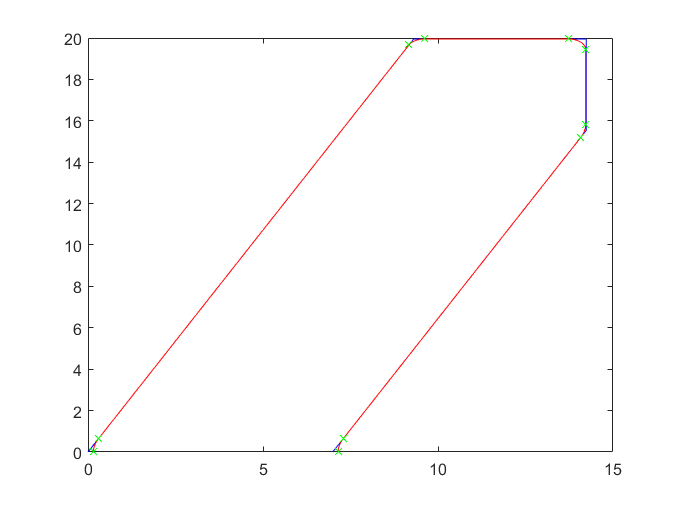

X_r = [x1_r, x2_r, x3_r, x4_r, x5_r];
Z_r = [z1_r, z2_r, z3_r, z4_r, z5_r];
hold on
plot(X_point, Z_point, 'b')
plot(X_r, Z_r, 'r')
plot(x_temp,z_temp, 'gx')
hold off

l12 = sqrt(x2 - x1)^2 + (z2 - z1); 
l23 = sqrt((x3 - x2)^2 + (z3 - z2)^2);
l34 = sqrt((x4 - x3)^2 + (z4 - z3)^2);
l45 = sqrt((x5 - x4)^2 + (z5 - z4)^2);

#### 4.5. Центры участков

% КООРДИНАТЫ ЦЕНТРОВ ОТРЕЗКОВ
%% УЧАСТОК_1
for i = 1 : N12
    step12 = dx_12*(i-0.5);
    x1_midle(i) = cosd(angle)*step12;
    z1_midle(i) = sind(angle)*step12;
end

% УЧАСТОК 2
% заполнение масивов
for i = 1 : N23
    step23 = dx_23*(i-0.5);
    x2_midle(i) = x_point_2 + step23;
    z2_midle(i) = z_point_2;
end

% УЧАСТОК 3
for i = 1 : N34
    step34 = dx_34*(i-0.5);
    x3_midle(i) = x_point_3;
    z3_midle(i) = z_point_3 - step34;
end

for i = 1 : N45 
    step45 = dx_45*(i-0.5);
    x4_midle(i) = x_point_4 - step45*cosd(angle);
    z4_midle(i) = z_point_4 - step45*sind(angle);
end

% УЧАСТЕК НАД ЗЕМЛЕЙ
Xu_midle = horzcat(x1_midle,x2_midle,x3_midle,x4_midle); % under
Zu_midle = horzcat(z1_midle,z2_midle,z3_midle,z4_midle);

% УЧАСТОК ПОД ЗЕМЛЕЙ
Xi_midle = flip(Xu_midle); % inverse
Zi_midle= flip(-Zu_midle);

% ФИНАЛЬНЫЕ ЦЕНТРЫ УЧАСТКОВ
x_midle = [Xu_midle,Xi_midle];
z_midle = [Zu_midle,Zi_midle];

figure;
plot(x_midle, z_midle);
title('Центры отрезков разбиения на антенне'); 

% график ВСЕЙ антенны с излучателями
figure;
plot(x_midle,z_midle,x1_antenn,z1_antenn, '-ro', x2_antenn, z2_antenn, '-ro');
title('Полная антенная с излучателями'); 